1) Create the MA(1) model, $X_t=Z_t+0.7Z_{t-1}$ with $Z_t\sim \text{IID}(0,1)$, and simulate a sample path of size $T$:

mdl = arima('Constant', 0, 'MA', 0.7, 'Variance', 1);
rng(153); % Fix the seed of the random number generator.
T = 500;  % Sample size
X = simulate(mdl, T);

2) Calculate the concentrated log-likelihood for different values of $\theta$ between 1 and -1 and plot the result (check whether the maximum of the log-likelihood appears near the true value of $\theta$):

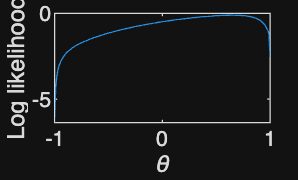

theta = -1:0.01:1;
logL = arrayfun(@(v) loglik(X, v), theta);

plot(theta, logL);
xlabel('\theta'); ylabel('Log likelihood');

3) Use the built-in `fminsearch` function to find the actual maximizer of $\ln \tilde{L}(\theta)$, i.e., the ML estimate of $\theta$ (note that we minimize $-\ln \tilde{L}(\theta)$):

theta_opt = fminsearch(@(v) -loglik(X, v), 0);
display(['MLE: ', num2str(theta_opt)])

MLE: 0.64981


4) Simulate 1000 sample paths from the model and compute ML estimates of $\theta$ (discard noninvertible cases). Report the sample mean and the variance of the estimates:

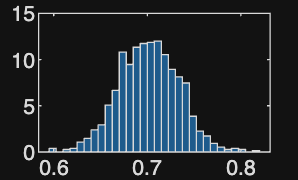

theta_hat = nan(1000, 1);

for i = 1 : 1000
    X = simulate(mdl, T);
    t = fminsearch(@(v) -loglik(X, v), 0);

    if abs(t) < 1
        theta_hat(i) = t;
    end
end

theta_hat(isnan(theta_hat)) = [];

histogram(theta_hat, 30, 'Normalization', 'pdf')

display(['Mean: ', num2str(mean(theta_hat))])

Mean: 0.70168


display(['Var.: ', num2str(var(theta_hat))])

Var.: 0.0010304


**Auxiliary functions:**

function Z = calc_z(X, Z0, theta)
    T = length(X);
    Z = zeros(T, 1);
    Z_prev = Z0;
    for t = 1:T
        Z(t) = X(t) - theta * Z_prev;
        Z_prev = Z(t);
    end
end


function l = loglik(X, theta)
    Z = calc_z(X, 0, theta);      
    SSE = sum(Z .^ 2);           
    T = length(X);
    l = -log(SSE / T);             
end
